# 1) Cruise Control.

### Cos'è il Cruise Control.

Il **Cruise Control** è un sistema elettronico che consente ad un veicolo di mantenere una velocità costante impostata dal conducente, senza la necessità di agire costantemente sull'acceleratore.

Principio di Funzionamento:

- **Impostazione della Velocità: **Il conducente imposta la velocità da mantenere, tramite pulsante o leva, e il sistema la memorizza come valore di riferimento.

- **Controllo della Velocità: **l'unità di controllo elettronico (**ECU**) monitora costantemente la velocità del veicolo tramite sensori (es, sensore di velocità). L'**ECU** confronta la velocità misurata con quella impostata: se è minore, l'ECU va ad agire sull'accelerazione per aumentarne la velocità, in caso contrario, si diminuisce l'accelerazione o si agisce sui freni.

- **Attuazione:** nel caso di motori a combustione, l'**ECU** agisce sull'acceleratore controllando elettronicamente l'iniezione del carburante e/o i freni, mentre per i veicoli elettrici si va ad agire direttamente sulla coppia (corrente) del motore. Per quest'ultimi, la gestione della decelerazione può essere gestita più facilmente sfruttando la frenata rigenerativa.

- **Disattivazione: **Il cruise control si disattiva automaticamente quando si preme il pedale del freno o anche tramite pulsante dedicato.

# 2) Analisi del modello Fisico.

### Descrizione del modello Fisico

Il **Cruise Control** è un sistema a retroazione con lo scopo di controllare la velocità di crociera e mantenere costante la velocità del veicolo nonostante i disturbi esterni, come le variazioni del vento o della pendenza della strada. Ciò avviene misurando la velocità del veicolo, confrontandola conquella di riferimento e regolando automaticamente l'acceleratore in base a una legge di controllo.

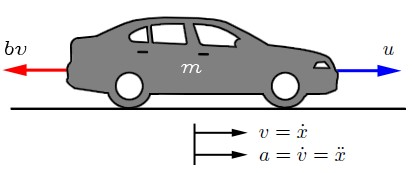

Si considera un semplice modello della dinamica del veicolo, mostrato nel diagramma a corpo libero (immagine sopra). Sul veicolo, di massa **m**, agisce una forza di controllo **u, **che rappresenta la forza generata all'interfaccia strada/pneumatico. In questo caso si assume di poterla controllare direttamente trascurando l'attrito dei pneumatici, della pendenza della strada ecc. che contribuiscono a generare le forze resistive. Per questo modello si considera l'**attrito viscoso **$\textrm{bv}$ (resistenza dell'aria) ipotizzando che vari linearmente con la **velocità del veicolo **$v$ e che agisca in direzione opposta al moto. La forma linearizzata dell'attrito viscoso vale per basse velocità fintanto che il moto dell'aria risulta essere laminare.

### **Equazione del modello Fisico.**

Un modo per descrivere i **Sistemi Complessi** è quello di analizzarli nel dominio del tempo e le grandezze che variano (nel tempo) possono essere definite dalle relazioni in termini di **Equazioni Differenziali**. La soluzione a queste equazioni fornisce il **legame ingresso-uscita** che dipende dal segnale in ingresso e dalle condizioni al contorno. Si ha quindi, per questo Sistema, che sommando le forze nella direzione **x** e applicando la seconda legge di Newton, si ottiene la seguente equazione:


$$\sum m\dot{v} =u-\textrm{bv}\to m\dot{v} +\textrm{bv}=u$$


che rapprsenta un'**Equazione Differenziale del primo ordine**, Lineare Tempo Invariante** (LTI)** dove i **coefficienti** non dipendono dal tempo e la soluzione dipende solo dalle condizioni iniziali**. **Dal momento che si è interessati a controllare la **velocità** del veicolo, l'equazione di uscita può essere scritta come:


$$y=v$$


### **Descrizione del modello fisico con Equazioni di Spazio di Stato.**

Data la precedente** Equazione Differenziale **e generalizzata in questa forma: 


$$\sum_{i\;=\;0}^n {\;a}_i \;\;\frac{{\mathrm{d}}^i }{\mathrm{d}t^i }y\left(t\right)=u\left(t\right)$$


può essere descritta da un modello **Spazio di Stato**, che è una rappresentazione matematica di un sistema fisico come un insieme di variabili di input, di output e di stato correlate da **Equazioni Differenziali del Primo Ordine**. Le variabili di stato definiscono i valori delle variabili di output. Di seguito il modello nella forma standard:


$$\left\lbrace \begin{array}{ll}
\dot{\mathit{\mathbf{x}}} =\textrm{Ax}+\textrm{Bu} & \\
y=\textrm{Cx}+\textrm{Du} & 
\end{array}\right.$$


Dove:

- $x$ : vettore di stato delle variabili (nx1). 

- $\dot{x} \;$: derivata (rispetto il tempo) del vettore di stato (nx1).

- $u\;$: input o vettore di cotrollo (px1).

- $y$: vettore di output (qx1).

- $A$: matrice di sistema (nxn).

- $B$: matrice di input (nxp).

- $C$: matrice di output (qxn).

- $D$: matrice di feedforward (qxp)

In particolare la matrice di uscita $C\;$viene utilizzata per specificare quali variabili di stato (o combinazioni di esse) sono disponibili per l'utilizzo da parte del controllore. Dal momento che si è interessati a controllare la velocità del Sistema, si esplicita l'**Equazione Differenziale** in funzione di $v$:


$$\left\lbrace \begin{array}{ll}
\dot{v} =-\frac{\mathrm{b}}{m}v+\frac{u}{m} & \\
y=x & 
\end{array}\right.$$


In questo caso il sistema **Cruise Control**, descritto da una sola **Equazione Differenziale**, lo si rappresenta tramite **Equazioni di Spazio di Stato**:


$$\left\lbrack \dot{v} \right\rbrack =\left\lbrack \frac{-b}{m}\right\rbrack \left\lbrack v\right\rbrack +\left\lbrack \frac{1}{m}\right\rbrack \left\lbrack u\right\rbrack$$


Il Tool di simulazione **Matlab**, permette di utilizzare la funzione `ss` per  convertire modelli di sistemi dinamici nella forma di **modello stato-spazio** che risulta essere utile per Rappresentare un modello** Lineare Tempo Invariante (LTI)** ed eseguire la progettazione di controllo, che è lo scopo di questo elaborato.

% Preparazione dello script.
clc
clear
close all

% Dati del sistema.
m = 1000; % Massa del veicolo [kg].
b = 50;   % Coefficiente di attrito viscoso [Ns/m].
u = 500;  % Forza applicata al sistema [N].

% Matrici stato-spazio.
A = -b/m;
B = 1/m;
C = 1;
D = 0;

% Rappresentazione del sistema in forma di Spazio di Stato.
ss_cruise = ss(A,B,C,D)


ss_cruise =
 
  A = 
          x1
   x1  -0.05
 
  B = 
          u1
   x1  0.001
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


### **Descrizione del modello fisico con Trasformata di Laplace.**

Per risolvere le **Equazioni Differenziali Lineari **risulta conveniente descrivere il problema di origine attraverso una trasformazione reversibile. Uno strumento che, dato un segnale di ingresso qualsiasi, fornisca calcoli semplici è dato dalla trasformazione dei sistemi dal dominio nel **tempo** a dominio **s**. Questo strumento è dato dalla **Trasformata di Laplace** dove la risoluzione di **Equazioni Differenziali **viene semplificata portando alla soluzioni di **Equazioni Lineari Algebriche**. La **Funzione di Trasferimento** di un sistema lineare è definito come il rapporto della trasformata di **Laplace** della variabile di uscita $Y\left(s\right)$ rispetto quella della variabile in ingresso $U\left(s\right)$, con tutte le condizioni iniziali poste a zero. La **FdT** di un generico sistema fisico è dato da:


$$F\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}$$


che risulta essere un rapporto tra polinomi a coefficienti costanti e reali in **s**, dove il grado del polinomio al denominatore deve essere maggiore o uguale al grado del polinomio al numeratore. 

### **Rappresentazione del modello fisico con Schemi a Blocchi.**

In presenza di **SIstemi Complessi** risulta essere molto utile rappresentare la **Funzione di Trasferimento** tramite **Schemi a Blocchi**, dove l'azione causa-effetto è rappresentato da un blocco rettangolare e da un segmento entrate (ingresso) da uno uscente (uscita). Il **Cruise Control** è un sistema la cui FdT può essere descritto da il seguente schema: 

dove si ha:

- $P\left(s\right)$: funzione di trasferimento.

- $U\left(s\right)$: ingresso.

- $V\left(s\right)$: uscita.

 L' **Equazione Differenziale **che descrive il **Cruise Control** può essere riscritta in forma di Laplace come segue:


$$m\dot{v} +\textrm{bv}=u\to \textrm{msV}\left(s\right)\;+\textrm{bV}\left(s\right)=U\left(s\right)$$


si esplicita l'equazione rispetto la variabile di uscita e si porta la variabile di ingresso al denominatore. La **Fdt** del processo risulta essere:


$$V\left(s\right)\left(b+\textrm{ms}\right)=U\left(s\right)\to P\left(s\right)=\frac{V\left(s\right)}{U\left(s\right)}=\frac{1}{b+\textrm{ms}}\;\left\lbrack \frac{m/s}{N}\right\rbrack$$


e può essere riscritta in forma canonica:


$$P\left(s\right)=\frac{1}{b+\textrm{ms}}=\frac{K}{1+\tau s}\;\;\;\;\textrm{con}\;\left\lbrace \begin{array}{ll}
K=\frac{1}{b} & \\
\tau =\frac{m}{b} & 
\end{array}\right.$$


**Matlab** mette a disposizione diversi strumenti per convertire modelli di **Sistemi Dinamici** in forma di funzioni di trasferimento:

- **ss2tf**: converte la rappresentazione dello spazio di stato in funzione di trasferimento.

- **tf**: rappresenta il modello della funzione di trasferimento.

% Conversione del sistema in funzione di trasferimento
[num,den] = ss2tf(A,B,C,D);

tf_cruise_ = tf(num,den)


tf_cruise_ =
 
   0.001
  --------
  s + 0.05
 
Continuous-time transfer function.
Model Properties


Rappresentazione in Forma Canonica.

% Forma canonica.
K = 1/b;
Tau_p = m/b;

s = tf('s'); % Creazione variabile 's'.
P = K/(1 + Tau_p*s) % FdT del processo 'P' (Cruise Control).


P =
 
    0.02
  --------
  20 s + 1
 
Continuous-time transfer function.
Model Properties


# 3) Analisi del sistema.

### **Sistema a Catena Aperta.**

Un controllore ad **Anello Aperto** è un sistema in cui l'uscita non viene misurata e utilizzata per regolare l'ingresso. Non ha quindi un meccanismo di feedback che gli permette di correggere eventuali errori o deviazioni rispetto l'uscita desiderata. Solitamente viene utilizzato nei casi in cui un processo evolve molto lentamente o il segnale di **uscita **$V\left(s\right)$ assume valori analoghi a quello in **ingresso **$U\left(s\right)$.

#### Stabilità del sistema.

La **Stabilita **del sistema è determinata dalla posizione dei **poli** della funzione di trasferimento nel piano complesso s. Un **Sistema Lineare Tempo-Invariante (LTI)** è stabile se e solo se tutti i **poli** della sua funzione di trasferimento hanno parte reale negativa e quindi si trovano nel semipiano sinistro del **piano s**. Per verificare questo si pongono i poli della **FdT **uguale a 0:


$$P\left(s\right)=\frac{1}{b+\textrm{ms}}\to b+\textrm{ms}=0\to s=-\frac{b}{m}\;\;\;\;\textrm{con}\;b,m>0\;\;$$


Il **Sistema** risulta avere un solo polo con parte reale negativa, quindi stabile. Per verificare queste condizioni, **Matlab** mette a disposizione diverse funzioni, alcune di queste sono:

- **pole**: restituisce i poli del sistema.

- **pzmap**: restituisce poli e zeri del sistema e li plotta.

% Poli del Sistema 'P'.
P_poli = pole(P)

P_poli = -0.0500

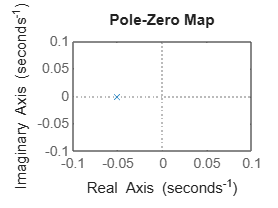


% Mappa dei poli del Sistema 'P'.
pzmap(P);
axis([-0.1 0.1 -0.1 0.1]);

**Specifiche di prestazione.**

Dal momento che il **Sistema** è stabile, si definiscono le specifiche da soddisfare:

- $\textrm{Tr}$ : Tempo di salita < 5 [s].

- $\textrm{Mp}$: Overshoot < 10 [%].

- $e_{\textrm{rr}}$: Errore a regime < 2 [%].

Si impone al sistema una forza **u** di 500 [N] per far raggiungere al veicolo una velocità ***v*** di 10 [m/s] (circa 36 [km/h]) dove si suppone che il veicolo sia in grado di raggingere quella velocità entro 5 [s] e il moto dell'aria ancora laminare (condizione per far valere la linearizzazione dell'attrito viscoso). Per verificarne le prestazioni, si stimola il **Sistema** con un segnale a gradino. Per ottenere questo, **Matlab** mette a disposizione le seguenti funzioni: 

- **step**: risposta a gradino di un sistema dinamico.

- **RespConfig**: configurazione della risposta a gradino.

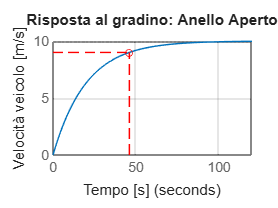

% Plot risposta a gradino.
respCfg = RespConfig('Amplitude',u);
[y,t] = step(P,respCfg);
stepplot(P,respCfg)

% Plot puntino rosso (Tempo di salita al 90%).
hold on
x_plot = t(51);
y_plot = y(51);
plot(x_plot,y_plot,'o','MarkerSize',5,'Color','r');
hold on

% Plot linee tratteggiate.
plot([0, x_plot], [y_plot, y_plot],'--','Color','r'); % Tratteggio orizzonale.
hold on
plot([x_plot, x_plot], [0, y_plot],'--','Color','r'); % Tratteggio verticale.
grid on;
hold off;

% Legenda.
title('Risposta al gradino: Anello Aperto');
xlabel('Tempo [s]');
ylabel('Velocità veicolo [m/s]');

Dalla figura della **risposta a gradino** si nota che il **Sistema **non ha **Overshoot** (risultato aspettato in quanto sistema del primo ordine) e la risposta a regime raggiunge la valocità desiderata di 10 [m/s], ma il **Tempo di Salita** (90% del tempo totale) lo raggiunge dopo circa 46 [s]. Dal momento che quest'ultima specifica non è rispettata, risulta necessario progettare un controllore a **Catena Chiusa** che permetta di raggiungere le prestazioni desiderate, mantenedo la stabilità del sistema.

### **Sistema a Catena Chiusa.**

Un controllore ad **Anello Chiuso**, detto anche sistema di controllo con **feedback**, è un sistema in cui l'uscita viene misurata e confrontata con l'ingresso desiderato, il **setpoint**. La differenza tra questi due valori, chiamata **errore**, viene utilizzata per regolare l'ingresso del sistema al fine di ridurlo al minimo e far sì che l'uscita segua il **setpoint**.

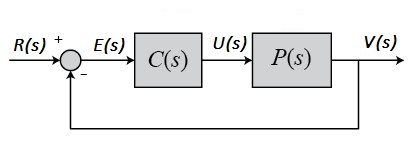

dove si ha:

- $C\left(s\right)$: FdT del controllore.

- $P\left(s\right)$: FdT del processo.

- $R\left(s\right)$: ingresso.

- $E\left(s\right)$: errore.

- $U\left(s\right)$: uscita del controllore.

- $V\left(s\right)$: uscita.

#### Sintesi manuale del controllore.

Per ottenere le prestazioni desiderate, si utilizza un regolatore **PI** (Proporzionale-Integrativo) che è un algoritmo di controllo ad **Anello Chiuso **che combina un'azione **proporzionale** e un'azione **integrativa,** per regolare l'uscita di un sistema in modo da farla corrispondere a un valore desiderato, il **setpoint**. Il **regolatore PI** introduce nella funzione di anello un **polo** nell origine e uno **zero** reale negativo, quindi è adatto a migliorare la precisione a regime dei sistemi di tipo 0 o 1, garantendo la stabilità. Il **PI** si comporta infatti, dal punto di vista della risposta in frequenza, come una rete ritardatrice con un polo nell origine. Pertanto, può migliorare il margine di fase per effetto dello **zero** ma determina una riduzione della larghezza di banda del sistema in anello chiuso. Data la funzione di trasferimento:


$$P\left(s\right)=\frac{1}{b+\textrm{ms}}=\frac{K}{1+\tau_p s}\;\;\;\;\textrm{con}\;\;K=\frac{1}{b},\tau_p =\frac{m}{b}$$


Per questa applicazione si utilizza un **Regolatore PI** che cancelli il polo reale negativo e indicato con $C\left(s\right)$:


$$C\left(s\right)=\textrm{PI}=K_p +\frac{K_i }{s}=\frac{K_i }{s}\left(1+\frac{K_p }{K_i }\right)=\;\frac{K_i }{s}\left(1+\tau_c s\right)\;\;\;\;\textrm{con}\;\tau_c =\frac{K_p }{K_i }$$


dove si ha:

- $K_p$: guadagno proporzionale.

- $K_i$: guadagno integrale.

- $\tau_c$: costante di tempo del regolatore $\textrm{PI}$.

Si considera il sistema ad **Anello Aperto** $L\left(s\right)=C\left(s\right)\cdot P\left(s\right)$ e si provvede alla cancellazione **zero-polo**:


$$L\left(s\right)=C\left(s\right)\cdot P\left(s\right)=\frac{K_i }{s}\left(1+\tau_c s\right)\cdot \frac{K}{1+\tau_p s}=\frac{K_i K\left(1+\tau_c s\right)}{s\left(1+\tau_p s\right)}$$
 

dal momento che $\tau_p$ è un valore noto, è possibile cancellare il **polo** ponendo: $\tau_c$ = $\tau_p$, si ottiene quindi: 


$$L\left(s\right)=\frac{K_i K\left(1+\tau_c s\right)}{s\left(1+\tau_p s\right)}=\frac{K_i K}{s}\;\;\;\;\textrm{con}\;\tau_c =\tau_p \to \frac{K_p }{K_i }=\frac{m}{b}=20\to K_p =20\cdot K_i$$


SI determina il valore di $K_i$ analizzando il sistema nel **dominio della frequenza** al valore della $\omega_c$ (omega critica) e quindi ponendo il modulo della funzione di trasferimento a catena aperta uguale a 1 (o a 0 $\textrm{dB}$, in scala logaritmica). In altre parole, è il punto in cui il guadagno del sistema, senza considerare il feedback, è unitario e dove si ha il massimo valore del **margine di fase**.


$$\left|L\left(j\omega_c \right)\right|=1\to \frac{K_i K}{\sqrt{{\left(j\omega_c \right)}^2 }}=\frac{K_i }{b\cdot \omega_c }=1\to K_i =b\cdot \omega_c$$


Per un sistema del primo ordine è possibile calcolare la $\omega_c$ tramite la seguente relazione:


$$\omega_c =\frac{4\ldotp 6}{T_s }\;\left\lbrack \frac{\textrm{rad}}{s}\right\rbrack$$


dove $T_s$ è il tempo di assestamento del sistema con errore a regime dell' $1%$ e che quindi soddisfa anche il requisito dell'**errore a regime** $e_{\textrm{rr}}$ del $2%$. In questo caso si pone $T_s =10\;\left\lbrack s\right\rbrack$ che è il tempo del sistema per arrivare a regime.


$$\omega_c =\frac{4\ldotp 6}{T_s }=\frac{4\ldotp 6}{10}=0\ldotp 46\;\left\lbrack \frac{\textrm{rad}}{s}\right\rbrack$$
 

si sostituisce nella formula precedente e si calcola il valore di $K_i$ e $K_p$:


$$\left\lbrace \begin{array}{ll}
K_i =b\cdot \omega_c \to 50\cdot 0\ldotp 46=23 & \\
K_p =20\cdot K_i =460 & 
\end{array}\right.$$


Per implemenare il controllore $\textrm{PI},$ **Matlab** metta a disposizione la funzione **pid** che permette di implementare il controllore **PI** passando come parametri in ingresso rispettivamente i guadagni di di $K_i$ e $K_p$. 

% Controllore PI.
Kp = 460; % Guadagno Kp.
Ki = 23;  % Guadagno Ki.
C = pid(Kp,Ki); % Controllore C(s) (pid).

Una volta implementato il controllore $C\left(s\right)$ si calcola la **FdT** ad anello aperto $L\left(s\right)$ e la si pone nel sistema ad anello chiuso $W\left(s\right):$


$$W\left(s\right)=\frac{L\left(s\right)}{1+L\left(s\right)}$$


% Sistema ad anello aperto.
L = C*P;

% Sistema ad anello chiuso.
W = feedback(L,1); 

Una volta determinata la funzione di trasferimento ad **anello chiuso**, si provvede a verificare se soddisfa i requisiti di prestazione scelti. Si utilizza la funzione **step** di Matlab, questa volta con un gradino di ampiezza $u=10\;\left\lbrack m/s\right\rbrack$ in quanto in catena chiusa la variabile di feedback è la **velocità**, che è il valore da controllare.

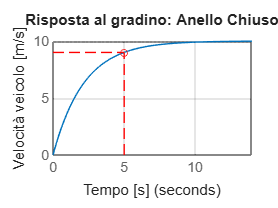

% Plot risposta a gradino.
u = 10; % Ampiezza del gradino. [m/s].
respCfg = RespConfig('Amplitude',u); % Configurazione del gradino.
[y,t] = step(W,respCfg);
stepplot(W,respCfg)

% Plot puntino rosso (Tempo di salita al 90%).
hold on;
x_plot = t(51);
y_plot = y(51);
plot(x_plot,y_plot,'o','MarkerSize',5,'Color','r');
hold on;

% Plot linee tratteggiate.
plot([0, x_plot], [y_plot, y_plot],'--','Color','r'); % Tratteggio orizzonale.
hold on;
plot([x_plot, x_plot], [0, y_plot],'--','Color','r'); % Tratteggio verticale.
grid on;
hold off;

% Legenda.
title('Risposta al gradino: Anello Chiuso');
xlabel('Tempo [s]');
ylabel('Velocità veicolo [m/s]');

Si verifica la stabilità del sistema a catena chiusa:

% Poli del Sistema 'P'.
W_poli = pole(W)

W_poli =    -0.4600
   -0.0500


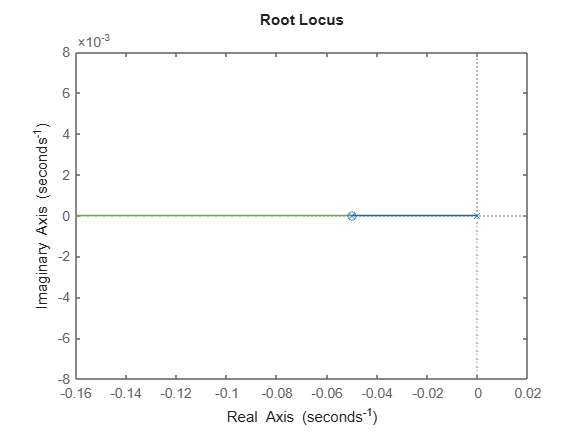

% Luogo delle radici.
rlocus(C*P);

Osservando il **luogo delle radici** si nota la presenza di un **polo** ed uno **zero** reali e coincidenti ($\omega_c =\omega_p =0\ldotp 05\;\left\lbrack \textrm{rad}/s\right\rbrack$) e che al variare di $K\;\textrm{da}\;\;0\to \infty$ si ha:

- un ramo che tende a $-\infty$, quindi stabile per tuti i valori di $K$.

- un ramo che tende a $0$, quindi non stabile per tutti i valori di $K$. In questo caso il sistema è **marginalmente stabile,** in quanto gli altri poli del sistema si trovano nel semipiano sinistro, ma può portare il sistema ad oscillazioni persistenti.

#### Sintesi del controllore con Matlab pidTuner.

L'app** PID Tuner** permette di sintetizzare automaticamente i guadagni di un controllore **PID** con l'obiettivo di raggiungere un equilibrio tra prestazioni e robustezza e quindi migliorare le prestazioni del controller in modo interattivo. È possibile specificare il tipo di controller come **PI, PD, PID**, ecc dove i grafici permettono di esaminare le prestazioni del controller nel dominio del tempo e della frequenza. Il Sistema da indicare nella funzione  **pidTuner** è il processo $L\left(s\right)$ a catena aperta.

Nell'app** PID Tuner, **indicando i valori di **Transient Time** a 4.35 [s] e **Transient Behaviour** a 0.9 si ottengono gli stessi risultati della taratura manuale, a conferma dei calcoli effettuati manualmente. Sempre con l'app di **Matlab** si provano a calcolare altri valori di $K_p \;e\;K_i$ che rendano il **Tempo di Salita **$T_r$ più lineare e quindi più idone ad un'applicazione reale. Dopo alcuni tentativi, impostando rispettivamente nei due parametri precedenti, i valori 5.943 [s] e 0.756, si ottengono $K_p =313\ldotp 7\;e\;K_i =44\ldotp 5$.

% pidTuner(P,'PI');
Kp_pt = 313.7;
Ki_pt = 44.5;
C_pt = pid(Kp_pt,Ki_pt);
W_pt = feedback(C_pt*P,1)


W_pt =
 
      6.274 s + 0.89
  -----------------------
  20 s^2 + 7.274 s + 0.89
 
Continuous-time transfer function.
Model Properties


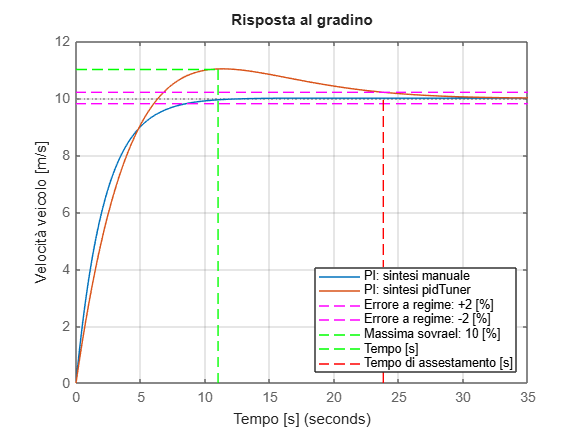

% Risposta al gradino dei due sistemi.
u = 10; % Ampiezza del gradino [m/s].
respCfg = RespConfig('Amplitude',u); % Configurazione del gradino.

% FdT con PI tarato manualmente.
step(W,respCfg); 
hold on;

% FdT con PI tarato con pidTuner.
step(W_pt,respCfg) 
grid on;

% Plot linee errore a regime: 2 [%].
t_plot = 35; % Durata tot. plot [s].
plot([0, t_plot], [(u+u*(0.02)), (u+u*(0.02))],'--','Color','magenta'); 
hold on;
plot([0, t_plot], [(u-u*(0.02)), (u-u*(0.02))],'--','Color','magenta'); 
hold on;

% Plot linee tratteggiate massima sovraelongazione: 10 [%].
t_max_ovt = 11; % Tempo con max overshoot [s].
plot([0, t_max_ovt], [t_max_ovt, t_max_ovt],'--','Color','g'); 
hold on;
plot([t_max_ovt, t_max_ovt], [0, t_max_ovt],'--','Color','g'); 
hold on;

% Plot linea tratteggiata tempo di assestamento: 23.8 [s].
t_ass = 23.8; % Tempo di assestamento [s].
plot([t_ass, t_ass], [0, (u+0.02)],'--','Color','red'); 
grid on;
hold off;

% Legenda.
title('Risposta al gradino');
xlabel('Tempo [s]');
ylabel('Velocità veicolo [m/s]');
legend('PI: sintesi manuale','PI: sintesi pidTuner', ...
       'Errore a regime: +2 [%]', 'Errore a regime: -2 [%]', ...
       'Massima sovrael: 10 [%]','Tempo [s]','Tempo di assestamento [s]');
legend('Location','southeast');

#### Stabilità del sistema.

Come si può vedere dal grafico della risposta a gradino, la linea arancio (taratura PI con pidTuner) presenta due poli complessi coniugati a parte reale negativa. Questo significa che il **sistema** ha un transitorio rapido con accumulo e dissipazione oscillante dell'energia. La **stabilità** è confermata dal fatto che i 2 poli sono a parte reale negativa e dall'ampio margine di fase (**diagramma di** **Bode**). 

% Poli.
W_pt_poli = pole(W_pt)

W_pt_poli =   -0.1819 + 0.1069i
  -0.1819 - 0.1069i


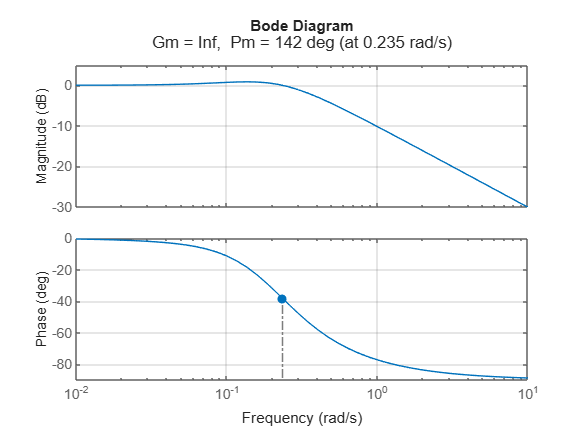

% Margine di fase.
margin(W_pt);
grid on;

#### Verifica delle specifiche di prestazione.

Tramite le seguenti formule si verifica se la funzione di trasferimento calcolata tramite **Matlab pidTuner** soddisfa le specifiche di progetto. Si calcola il **coefficiente di smorzamento** $\xi_{\min }$ che serve a garantire la **sovraelongazione **$M_p$ entro il valore massimo del 10%: 


$$\xi_{\min } \ge \sqrt{\frac{\ln^2 \left(M_p \right)}{\pi^2 +\ln^2 \left(M_p \right)}}=\sqrt{\frac{\ln^2 \left(10\right)}{\pi^2 +\ln^2 \left(10\right)}}\approx 0\ldotp 6$$


ed il valore di $\alpha_{\min }$ che indica il valore minimo della parte reale dei poli complessi coniugati per ottenere un **tempo di assestamento **$T_s$ al $2%$:


$$\alpha_{\min } =\zeta_{\min } \cdot \omega_n =0\ldotp 6\cdot 0\ldotp 235\approx 0\ldotp 141\;\left\lbrack \textrm{rad}/s\right\rbrack$$


Per determinare il **tempo di assestamento** entro il 2% per il **sistema** in questione, si deve risolvere la seguente disuguaglianza:


$$e^{-\zeta \omega_n T_s } \le e_{\textrm{rr}%} \to T_s \ge \frac{\left.\ln {\left(e\right.}_{\textrm{rr}%} \right)}{\zeta \omega_n }=\frac{\left.\ln {\left(e\right.}_{\textrm{rr}%} \right)}{\alpha_{\min } }=\frac{\ln \left(0\ldotp 02\right)}{0\ldotp 141}\approx 28\;\left\lbrack s\right\rbrack$$


Dal grafico della risposta al gradino si può notare si che il valore massimo di **sovraelongazione** è al $10%$ ed il** tempo di assestamento** a $23\ldotp 8\left\lbrack s\right\rbrack$. Si può dire quindi che i requisiti di prestazione sono soddisfatti.

Nel diagramma del **Luogo delle Radici** è possibile sia visualizzare l'andandamento dei **poli **che il valore delle **radici,** per un **sistema LTI** ad **anello chiuso, **al variare di $K\;\textrm{da}\;0\to \infty$ nel piano complesso $s$. Lo scopo principale è quello di:

- **Analisi di stabilità**: determinare i valori di $K$per la quale il sistema diventa instabile.

- **Analisi delle performance**: la posizione dei **poli**, fornisce informazioni relativo al transitorio e quindi: coefficiente di smorzamento $\zeta$, pulsazione naturale $\omega_n$, tempo di salita $T_r$ e tempo di assestamento $T_s$.

- **Design del controllore**: sintetizzare il controllore (es, PI, PID, ecc) piazzando i poli del sistema ad anello chiuso in regioni desiderate per soddisfare i requisiti. 

Tramite la funzione Matlab **rlocus** è possibile plottare il **Luogo della radice** del sistema (passando come argomento la funzione ad anello aperto $C\left(s\right)\cdot P\left(s\right)$), mentre con **sgrid** si applica una griglia dove i **semicerchi** corrispondono a poli complessi coniugati con stessa **pulsazione naturale **$\omega_n$ e le **semirette** a poli complessi coniugati con stesso **coefficiente di smorzamento **$\zeta$.

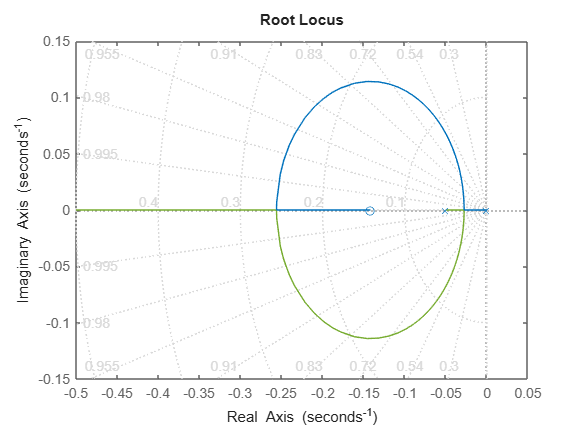

Psi = 0.6; % Coefficiente di Smorzamento [-].
Wn = 0.235; % Pulsazione Naturale sistema ad anello chiuso [rad/s].
a = Psi*Wn; % Valore minimo parte reale poli complessi coniugati.

% Plot del Luogo delle Radici.
rlocus(C_pt*P);
sgrid(Psi,a);
hold off;

Dal diagramma si nota che il **LdR **è formato da due rami, tanti quanti sono i poli della** FdT ad anello aperto**. I rami partono dai **poli**, segnati con una **x,** del sistema ad anello aperto (denominatore di$L\left(s\right)=0$): uno finisce nello **zero** (numeratore della $L\left(s\right)=0$) segnati con una **o**, mentre l'altro tende ad infinito seguendo l'asintoto. L'**angolo** dell'asintoto è dato dalla relazione:


$$\textrm{𝛼}=\frac{{180}^{\degree } +ℎ\cdot {360}^{\degree } }{\textrm{𝑛}-\textrm{𝑚}}\;\;\textrm{con}\;ℎ\in N\to \;\alpha =\frac{{180}^{\degree } +0\cdot {360}^{\degree } }{2-1}={180}^{\degree }$$


dove si ha:

- $\alpha$: angolo dell'asintoto.

- $n$: numero di poli.

- $m$: numero di zeri.

Il sistema risulta essere **stabile** e garantisce le **prestazioni** indicate nei requisiti se i poli complessi coniugati rimango all'interno dell'area delimitata da:

- $\zeta$$>\xi_{\min }$: garantisce sovraelongazione massima. 

- $\alpha >\alpha_{\min }$: garantisce tempo di assestamento.

#### Errore a regime (Teorema del valore finale).

Il **teorema del valore finale** permette di determinare il comportamento a regime (cioè per t che tende ad infinito o s che tende a 0) di un sistema dinamico lineare tempo-invariante (LTI) a partire dalla sua funzione di trasferimento nel dominio di Laplace.


$$\lim_{t\to \infty } x\left(t\right)=\lim_{s\to 0} \;s\cdot X\left(s\right)$$


Il sistema in questione risulta essere **stabile** e quindi è possibile applicare il teorema:


$$\textrm{Ess}=\lim_{s\to 0} \;s\cdot E\left(s\right)=s\frac{U\left(s\right)}{1+L\left(s\right)}=s\cdot \frac{1}{s}\cdot \frac{1}{\frac{K_i }{b}\cdot \frac{1}{s}}=\frac{1}{\infty }\approx 0$$


dove si ha:

- $E\left(s\right)$: errore finale.

- $U\left(s\right)$: segnale in ingresso al sistema (segnale a gradino in questo caso).

- $L\left(s\right)$: funzione ad anello aperto.

Il sistema risulta avere valore **nullo** a regime.